%% --- Parameters ---
fs = 44100;          % Sampling frequency (Hz)
Tsym = 0.1;          % Symbol duration (seconds)
tSym = 0:1/fs:Tsym-1/fs; % Time vector for one symbol

% DFMT tone table: 2 bits per symbol
toneTable = [1000 1500; 1000 2000; 1500 2500; 2000 2500];
nTones = unique(toneTable(:))';

% Command words
commands = {'le','ri','fo','ba'}; % left, right, forward, backward
cmd = 'le'; % Change this to whatever way it should drive

%% --- Sender side ---
% Convert command to binary ASCII
binStr = reshape(dec2bin(cmd,8).'-'0',1,[]);

% Pad to pairs (2 bits per symbol)
if mod(length(binStr),2) ~= 0
    binStr = [binStr 0]; 
end

% Checksum (simple parity)
checksum = mod(sum(binStr),2);
txBits = [binStr checksum 0]; % Add dummy bit if necessary

% Group into 2-bit symbols
txSym = reshape(txBits,2,[])';
nSym = size(txSym,1);

% Generate DFMT signal
signal = [];
for i = 1:nSym
    idx = bin2dec(sprintf('%d', txSym(i,:))) + 1; % Map 2 bits → toneTable row
    freqs = toneTable(idx,:);
    s = sin(2*pi*freqs(1)*tSym) + sin(2*pi*freqs(2)*tSym);
    signal = [signal s];
end
signal = signal / max(abs(signal));

% Optional: simulate noise
rxSignal = signal + 0.02*randn(size(signal));

%% --- Receiver side ---
rxBits = [];
for i = 1:nSym
    seg = rxSignal( (1:length(tSym)) + (i-1)*length(tSym) );

    % Compute magnitude for each candidate frequency
    power = zeros(1,length(nTones));
    for j = 1:length(nTones)
        f = nTones(j);
        ref = sin(2*pi*f*tSym);
        power(j) = sum(seg.*ref).^2;
    end

    % Pick top two peaks
    [~,idx] = maxk(power,2);
    freqsDetected = sort(nTones(idx));

    % Find corresponding row in tone table
    [~,row] = ismember(freqsDetected, toneTable, 'rows');

    % Convert row → 2 bits (without de2bi)
    bits = bitget(row-1, 2:-1:1);
    rxBits = [rxBits bits];
end

% Remove dummy & checksum
rxBitsData = rxBits(1:end-2);
rxChecksum = mod(sum(rxBitsData),2);

% Check checksum
if rxChecksum ~= checksum
    disp('Checksum failed!');
else
    disp('Checksum OK');
end

Checksum OK



% Convert bits → ASCII
rxChars = char(bin2dec(reshape(char(rxBitsData+'0'),8,[]).')).';
fprintf('Received command: %s\n',rxChars);

Received command: le



%% --- Map command → robot action ---
% Example motor control (range -1 to 1)
leftMotor = 0; rightMotor = 0;
switch rxChars
    case 'le' % left
        leftMotor = 0.5; 
        rightMotor = 1.0;
    case 'ri' % right
        leftMotor = 1.0; 
        rightMotor = 0.5;
    case 'fo' % forward
        leftMotor = 1.0; 
        rightMotor = 1.0;
    case 'ba' % backward
        leftMotor = -1.0; 
        rightMotor = -1.0;
end

fprintf('Left motor: %.2f | Right motor: %.2f\n', leftMotor, rightMotor);

Left motor: 0.50 | Right motor: 1.00


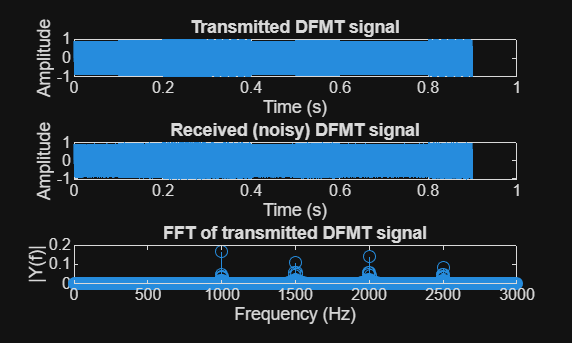


%% --- Visualization ---
t = (0:length(signal)-1)/fs;
figure;
subplot(3,1,1)
plot(t, signal)
title('Transmitted DFMT signal')
xlabel('Time (s)'), ylabel('Amplitude')
subplot(3,1,2)
plot(t, rxSignal)
title('Received (noisy) DFMT signal')
xlabel('Time (s)'), ylabel('Amplitude')

%% --- FFT Analysis ---
Y = fft(signal);
N = length(signal);
fVec = (0:N-1)*(fs/N);
magnitude = abs(Y)/N;

% Only plot positive frequencies
half_N = floor(N/2);
f_half = fVec(1:half_N);
mag_half = magnitude(1:half_N);

subplot(3,1,3)
stem(f_half, mag_half)
title('FFT of transmitted DFMT signal')
xlabel('Frequency (Hz)'), ylabel('|Y(f)|')
xlim([0 3000]) % Zoom to relevant DFMT frequencies